%Script to control the ANN_Neuron_Test.m as a function and
%train different neural network topologies. The performance of these
%are extracted as well.
clear all
close all
clc
%functionality possible values: 'single training' 'multi training' 'getPrediction' 'plots'
%'getError' 'single trainingV2'
functionality = 'single trainingV2'
filename = 'NN_NatR_Bayesian_Logsig';
trainFcn = 'trainbr';
actFcn = 'logsig';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);
filename = 'NN_NatR_Bayesian_Tansig';
actFcn = 'tansig';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);
filename = 'NN_NatR_Bayesian_Purelin';
actFcn = 'purelin';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);
filename = 'NN_NatR_LM_Logsig';
trainFcn = 'trainlm';
actFcn = 'logsig';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);
filename = 'NN_NatR_LM_Tansig';
actFcn = 'tansig';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);
filename = 'NN_NatR_LM_Purelin';
actFcn = 'purelin';
ANN_Neuron_Test(filename,trainFcn,actFcn,functionality);

% Optimization process for the selection of the best 
% input configuration
clear all
close all
clc
functionality = 'single trainingV2';
%Version 1: Dataset split in 90-10, then split again in 90-10 (trainbr)
filename = 'NN_Bayesian_Tansig_AllData';
trainFcn = 'trainbr';
actFcn = 'tansig';
material = 1:7; %FR
tic
ANN_Neuron_Test(material,filename,trainFcn,actFcn,functionality);
toc

% Code for plotting the performance of the proposed configuration 
% of ANN
% In this version, the datset is initially divided at random in 90-10
% (tr,ts). This randomization is performed for each training session. The
% network performance against unkown data is calcualted at the end using
% the 10% isolated.
clear all
close all
clc
load('..\Experimental work\NN_FR_Bayesian_Tansig.mat');
tests = fieldnames(neuralnets.FR);
for i=1:length( tests )
    for j=1:length(neuralnets.FR.ff1)
        msError(i,j) = neuralnets.FR.(tests{i})(j).performance.pred_mse;
        nmaError(i,j) = neuralnets.FR.(tests{i})(j).performance.nmaError;
        nrmsError(i,j) = neuralnets.FR.(tests{i})(j).performance.nrmsError;
        r2Coeff(i,j) = neuralnets.FR.(tests{i})(j).performance.r2Coeff;
    end
end
g_mse = mean( msError,2 );
g_nrmse = 100*mean( nrmsError,2 );
g_nmae = 100*mean( nmaError,2 );
g_r2 = 100*mean( r2Coeff,2 );
bar3(msError);
title("MSE of Multiple Training Sessions")
yticklabels(tests);
bar3(nrmsError);
title("Normalized RMSE of Multiple Training Sessions")
yticklabels(tests);
bar3(nmaError);
title("Normalized MAD of Multiple Training Sessions")
yticklabels(tests);
bar3(r2Coeff);
title("R-Squared of Multiple Training Sessions")
yticklabels(tests);
bar(g_mse);
title("Generalization Error (MSE) from 10-fold training session")
xticklabels(tests);
bar(g_nrmse);
title("Generalization Error (RMSE) from 10-fold training session")
xticklabels(tests);
bar(g_nmae);
title("Generalization Error (NMAD) from 10-fold training session")
xticklabels(tests);
bar(g_r2);
title("Generalization Error (R2) from 10-fold training session")
xticklabels(tests);
%Do I need the R^2 value?

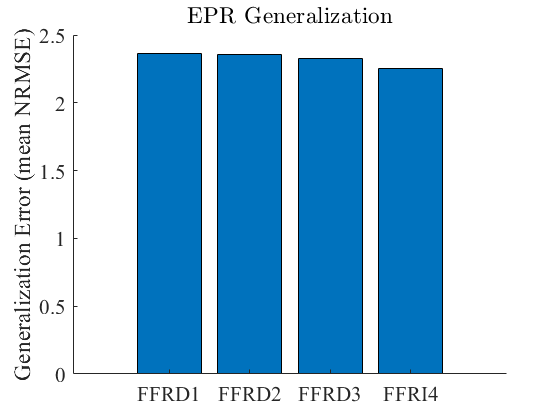

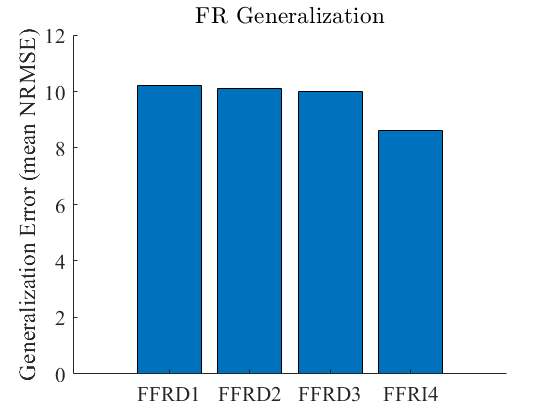

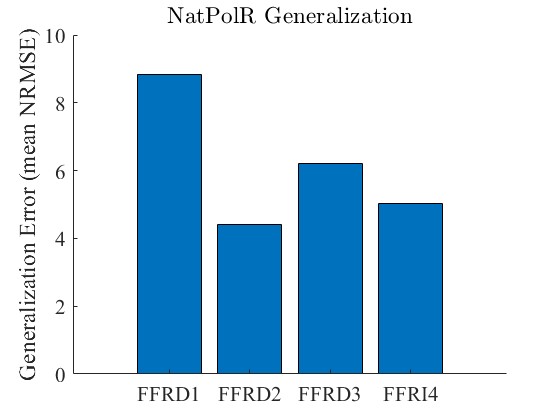

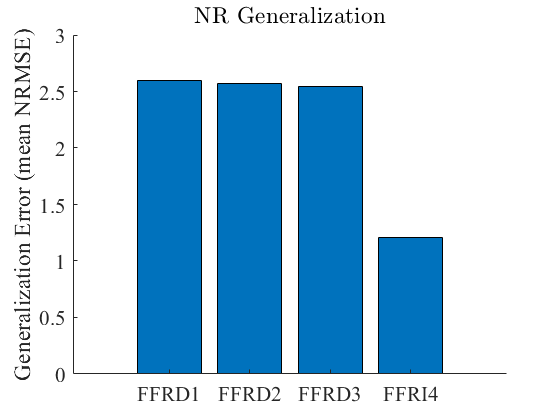

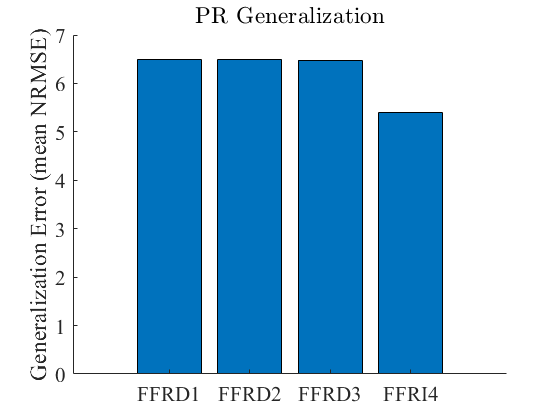

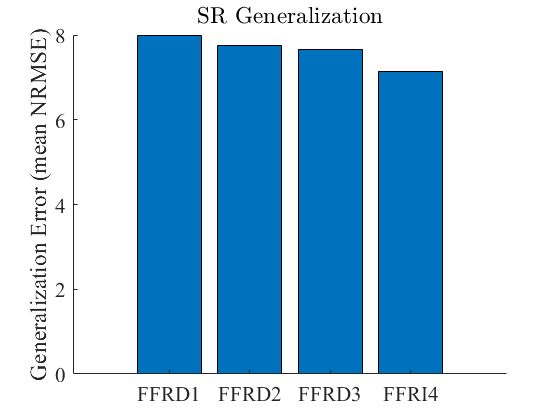

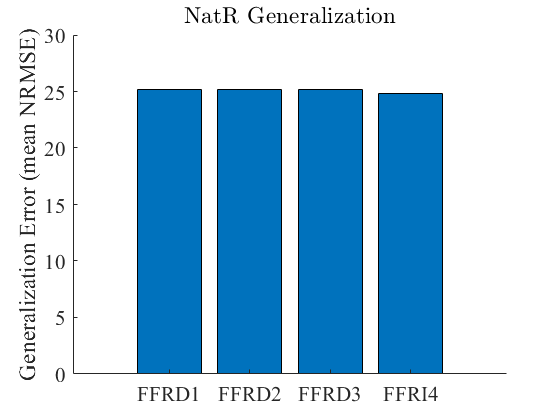

% Code for plotting the performance of the proposed configuration 
% of ANN. All materials

clear all
close all
clc
%Plot visualization
% Change default axes fonts.
set(groot,'DefaultAxesFontName', 'Times New Roman')
set(groot,'DefaultAxesFontSize', 16)
% Change default text fonts.
set(groot,'DefaultTextFontname', 'Times New Roman')
set(groot,'DefaultTextFontSize', 16)
% Extra
set(groot, 'DefaultLegendLocation', 'best')
set(groot, 'defaultLineLineWidth', 2)
if exist('neuralnets','var') == 0
    load('..\Experimental work\NN_Bayesian_Tansig_AllData.mat');
    % load('../Experimental work/NN_FR_Bayesian_Tansig1000.mat');
%     load('../Experimental work/FormattedTrainingSetIndV4.mat');
end
fields = fieldnames(neuralnets);
tests = fieldnames(neuralnets.FR);
totalNets = length(neuralnets.FR.ff1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %R2 Coefficient was incorrect. Recalculate and save it
% for i=1:length( fields)
% % for i=2
%     for j=1:length(tests)
%         %Placeholders for training data
%         x = trainData.(fields{i}).input_stress;
%         t = trainData.(fields{i}).output_stress*1e-6;
%         %Reshape x and t, to match network topology
%         switch tests{j}
%             case "ff1"
%                 x = x(:,1);
%             case "ff2"
%                 x = x(:,[1 2]);
%             case "ff3"
%                 x = [ x(:,[1 2 ]), t(:,2) ];
%             case "ff4"
%                 x = x(:,[1 4]);
%             case "ff5"
%                 x = x(:,[1 2 4]);
%             case "ff6"
%                 x = x(:,[1 2 4 5]);
%             case "ff7"
%                 x = [ x(:,[1 2 4 5]), t(:,2) ];
%             otherwise
%         end
%         t = t(:,1); %Single output
%         x = x';
%         t = t';
%         rng(0);
%         for k=1:totalNets
%            %Randomize the data and present to NN
%            Q = size(x, 2);
%            Q1 = floor(Q * 0.10); % Data division is 90-10 (train-test)
%            Q2 = Q - Q1;
%            ind = randperm(Q);
%            ind1 = ind(1:Q1);
%            ind2 = ind(Q1 + (1:Q2));
%            x1 = x(:, ind1);
%            t1 = t(:, ind1);
%            x2 = x(:, ind2);
%            t2 = t(:, ind2);
%            %Get prediction
%            y2 = neuralnets.(fields{i}).(tests{j})(k).NN(x2);
%            %Measurement of performance
%            %Calculate RMSE
%            varError = t2-y2; %t2 is experimental and y2 is predicted
%            sError = varError.^2;
%            msError = mean(sError);
%            rmsError = sqrt( msError);
%            nrmsError = rmsError / sqrt( mean( t2.^2 ) );
%            neuralnets.(fields{i}).(tests{j})(k).performance.nrmsError = nrmsError;
%            %Calculate NMAD
%            aError = abs(varError);
%            maError = mean(aError);
%            nmaError = maError / mean( abs( t2 ) );
%            neuralnets.(fields{i}).(tests{j})(k).performance.nmaError = nmaError;
%            %Calculate R^2
%            r2Coeff = 1 - ( sum( sError ) / sum( (t2 - mean(t2)).^2 ) ) ;
%            neuralnets.(fields{i}).(tests{j})(k).performance.r2Coeff = r2Coeff;
%        end
%     end    
% end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for a=1:length(fields)
% for a=2
    for i=1:length( tests )
        for j=1:length(neuralnets.(fields{a}).ff1)
            msError(i,j) = neuralnets.(fields{a}).(tests{i})(j).performance.pred_mse;
            nmaError(i,j) = neuralnets.(fields{a}).(tests{i})(j).performance.nmaError;
            nrmsError(i,j) = neuralnets.(fields{a}).(tests{i})(j).performance.nrmsError;
            r2Coeff(i,j) = neuralnets.(fields{a}).(tests{i})(j).performance.r2Coeff;
        end
    end
    g_mse = mean( msError,2 );
    g_nrmse = 100*mean( nrmsError,2 );
    g_nmae = 100*mean( nmaError,2 );
    g_r2 = 100*mean( r2Coeff,2 );
    figure
    bar(g_nrmse);
    ax = gca;   
    ax.Box = "off";
    ylabel("Generalization Error (mean NRMSE)");
    switch fields{a}
        case "NatR"
            plotName = "NatPolR";
        case "Nat100R"
            plotName = "NatR";
        otherwise
            plotName = fields{a};
    end
    strTitle = strcat(plotName," Generalization");
    title(strTitle,'Interpreter',"latex");
    xticklabels({'FFRD1','FFRD2','FFRD3','FFRI4'});
    pngfilename = strcat(plotName,"ANNGenE");
    saveas(gcf,pngfilename,'png');
end

%Script to assess the impact of the dataset size on the accuracy and
%generalization of the ANN
%10 different sizes are tested per material
%Use same hyperparameters as the input selection optimization
%10 neurons and 1 HL
%Focus on the ff3 configuration
clear all
clc
close all
load('../Experimental work/FormattedTrainingSetIndV4-10.mat'); %To extract placeholders
frootname = "../Experimental work/FormattedTrainingSetIndV4-";
noNeurons = 10;
fields.N = fieldnames(trainData);
N = length( fields.N ); 
tic
for i=1:N
    tic
    dataTests = 10;
    for j=1:dataTests
        fname = strcat(frootname,num2str(j*10),".mat");
        load(fname);
        x = trainData.(fields.N{i}).input_stress;
        t = trainData.(fields.N{i}).output_stress*1e-6;
        %Extract different portions
        clear newx newt
        new_x = [ x(:,[1 2]) , t(:,2) ];
        new_t = t(:,1);
        new_x = new_x'; new_t = new_t';        
        Q = size(x,1);
        Q1 = floor(Q * 0.90); % Data division is 90-10 (train-test)
        Q2 = Q - Q1;
        rng(0); %This make the randomization repeatable
        ind = randperm(Q);
        ind1 = ind(1:Q1);
        ind2 = ind(Q1 + (1:Q2));
        x1 = new_x( : , ind1); %Train
        t1 = new_t( : , ind1);
        x2 = new_x( : , ind2); %Test
        t2 = new_t( : , ind2);
        %Reshape to match ff3 configuration of: \\
        net = feedforwardnet(noNeurons,'trainbr');
        net.layers{1}.transferFcn = 'tansig'; %hidden layer
        net.layers{2}.transferFcn = 'purelin'; %output layer
        net.divideFcn = '';
        %Training
        [NN,tr] = train(net, x1, t1);
        y2 = NN(x2); %Get NN prediction using test set
        %Calculate mse because this was the performance function used
        %during training
        perfs = mse( NN, t2, y2 ); %Get mse from test set
        tr.in_pred = x2; %Inputs used for prediction
        tr.pred = y2;
        tr.pred_mse = perfs;
        %Calculate RMSE
        varError = t2-y2; %t2 is experimental and y2 is predicted
        sError = varError.^2;
        msError = mean(sError);
        rmsError = sqrt( msError);
        nrmsError = rmsError / sqrt( mean( t2.^2 ) );
        tr.nrmsError = nrmsError;
        %Calculate NMAD
        aError = abs(varError);
        maError = mean(aError);
        nmaError = maError / mean( abs( t2 ) );
        tr.nmaError = nmaError;
        %Calculate R^2
        r2Coeff = 1 - sum( sError ) / sum( (t2 - mean(t2)).^2 ) ;
        tr.r2Coeff = r2Coeff;
        neuralnets.(fields.N{i})(j).NN = NN;
        neuralnets.(fields.N{i})(j).performance = tr;
        neuralnets.(fields.N{i})(j).samples = Q;
    end    
    toc
end
save('../Experimental work/NN_SampleOp_Bayesian_Tansig.mat','neuralnets');
toc

%Script to plot the results from above test
clear all
clc 
close all
load('../Experimental work/NN_SampleOp_Bayesian_Tansig.mat');
fields.N = fieldnames(neuralnets);
N = length(fields.N);
for i=1:N
    M = length(neuralnets.(fields.N{i}));
    for j=1:M
        nrmsError(j) = neuralnets.(fields.N{i})(j).performance.nrmsError;
        r2Coeff(j) = neuralnets.(fields.N{i})(j).performance.r2Coeff;
        sampleVector(j) = neuralnets.(fields.N{i})(j).samples;
        effectPar(j) = neuralnets.(fields.N{i})(j).performance.gamk(end);
    end
    figure
%     loglog(sampleVector,nrmsError);
    semilogx(sampleVector,effectPar)
    ax = gca;   
    ax.Box = "off";
    ylabel("NRMSE");
    switch fields.N{i}
        case "NatR"
            plotName = "NatPolR";
        case "Nat100R"
            plotName = "NatR";
        otherwise
            plotName = fields.N{i};
    end
    strTitle = strcat(plotName," Generalization Error");
    title(strTitle,'Interpreter',"latex");
    ax.XTickLabelRotation = 45;
    %     xticklabels(tests);
    pngfilename = strcat(plotName,"ANNGenE");
    saveas(gcf,pngfilename,'png');
%     figure
%     semilogx(sampleVector,r2Coeff)
    
end

%Training algorithm. In here the number of neurons in the hidden layer is
%assessed. The minimum number of neurons is equal to the number of inpus.
%Similarly, the maximum number of neurons is three times the number of
%neurons. Multiple training is performed. Use the complete dataset in a 
% 90-10 division rate. The percentage of correct prediction could be done later. 
clear all
clc
close all
load('../Experimental work/FormattedTrainingSetIndV4-100.mat'); %To extract placeholders
noNeurons = 20;
fields.N = fieldnames(trainData);
N = length( fields.N ); 
tic
rng(0); %This make the randomization repeatable
for i=1:N
    msg = strcat("Current Material: ", fields.N{i});
    disp(msg);        
    noTraininng = 5;
    x = trainData.(fields.N{i}).input_stress;
    t = trainData.(fields.N{i}).output_stress*1e-6;
    NN = cell(noTraininng,noNeurons);
    tr = cell(noTraininng,noNeurons);
    for j=1
        msg = strcat("Current Training Sessiong: ", num2str(j));
        disp(msg);
        %Extract different portions
        clear newx newt
        %Reshape to match ff4 configuration
        new_x = x(:,[1 4]);
        new_t = t(:,1);
        new_x = new_x'; new_t = new_t';        
        Q = size(x,1);
        Q1 = floor(Q * 0.99); % Data division is 90-10 (train-test)
        Q2 = Q - Q1;
        ind = randperm(Q);
        ind1 = ind(1:Q1);
        ind2 = ind(Q1 + (1:Q2));
        x1 = new_x( : , ind1); %Train
        t1 = new_t( : , ind1);
        x2 = new_x( : , ind2); %Test
        t2 = new_t( : , ind2);        
        %For the final test use optimalNeurons in this for loop. And also
        %set outer loop to be only one training session
        optimalNeurons = [6,10,10,6,7,6,10 ];
        for k=optimalNeurons(i)
            msg = strcat("Current # Nuerons: ", num2str(k));
            disp(msg);        
            net = feedforwardnet(k,'trainbr');
            net.layers{1}.transferFcn = 'tansig'; %hidden layer
            net.layers{2}.transferFcn = 'purelin'; %output layer
            net.divideFcn = '';
            %Training
            [NN{j,k},tr{j,k}] = train(net, x1, t1);
            y2 = NN{j,k}(x2); %Get NN prediction using test set
            %Calculate mse because this was the performance function used
            %during training
            perfs = mse( NN{j,k}, t2, y2 ); %Get mse from test set
            tr{j,k}.in_pred = x2; %Inputs used for prediction
            tr{j,k}.pred = y2;
            tr{j,k}.pred_mse = perfs;
            %Calculate RMSE
            varError = t2-y2; %t2 is experimental and y2 is predicted
            sError = varError.^2;
            msError = mean(sError);
            rmsError = sqrt( msError);
            nrmsError = rmsError / sqrt( mean( t2.^2 ) );
            tr{j,k}.rmsError = rmsError;
            tr{j,k}.nrmsError = nrmsError;
            %Calculate NMAD
            aError = abs(varError);
            maError = mean(aError);
            nmaError = maError / mean( abs( t2 ) );
            tr{j,k}.maError = maError;
            tr{j,k}.nmaError = nmaError;
            %Calculate R^2
            r2Coeff = 1 - sum( sError ) / sum( (t2 - mean(t2)).^2 ) ;
            tr{j,k}.r2Coeff = r2Coeff;
        end        
    end
    neuralnets.(fields.N{i}).NN = NN;
    neuralnets.(fields.N{i}).performance = tr;
end

Current Material: EPR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 6


Current Material: FR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 10


Current Material: NatR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 10


Current Material: NR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 6


Current Material: PR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 7


Current Material: SR


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 6


Current Material: Nat100R


Current Training Sessiong: 1


optimalNeurons =      6    10    10     6     7     6    10


Current # Nuerons: 10


save('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig-Optimal.mat','neuralnets');
toc

Elapsed time is 242.522989 seconds.


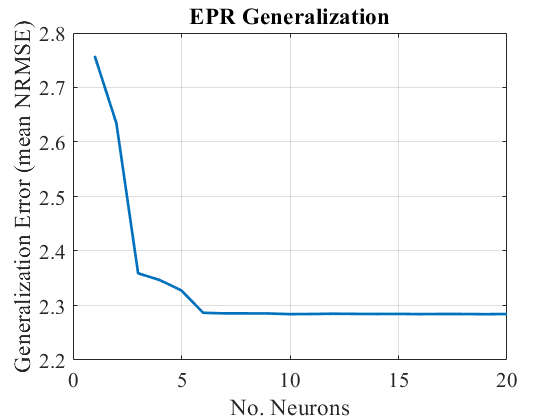

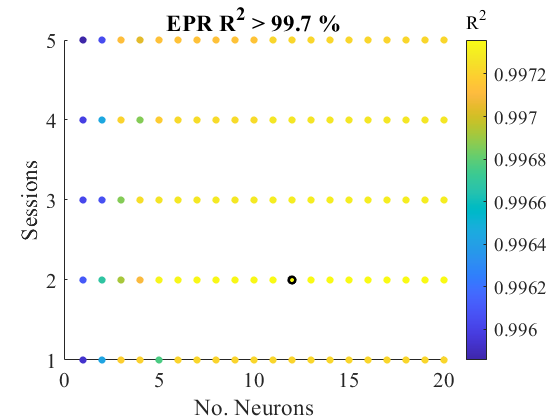

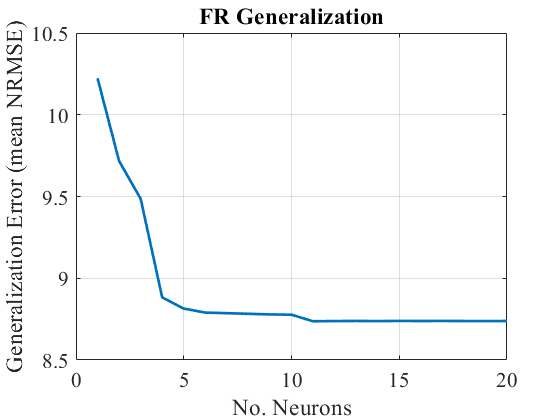

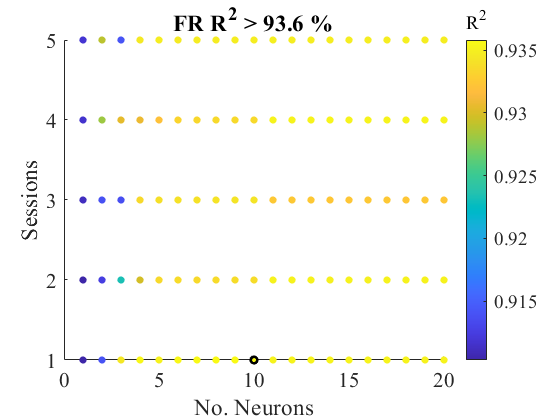

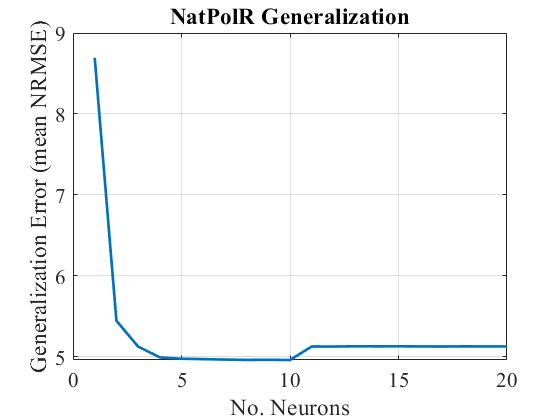

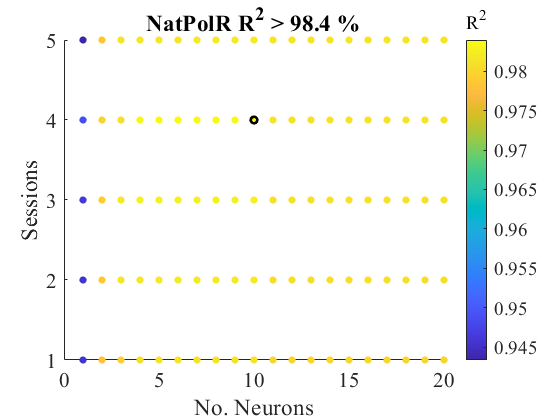

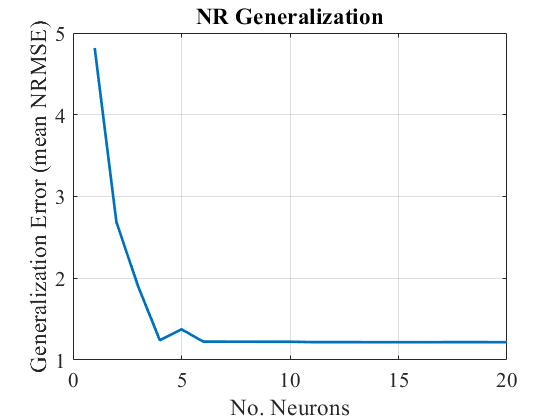

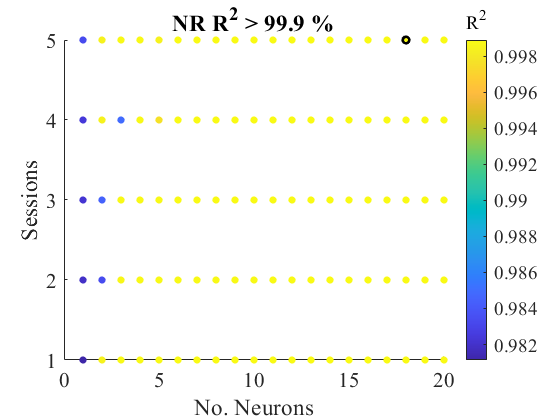

%Script to plot matrix of R-squared values
clear all
clc
close all
%Plot visualization
% Change default axes fonts.
set(groot,'DefaultAxesFontName', 'Times New Roman')
set(groot,'DefaultAxesFontSize', 16)
% Change default text fonts.
set(groot,'DefaultTextFontname', 'Times New Roman')
set(groot,'DefaultTextFontSize', 16)
% Extra
set(groot, 'DefaultLegendLocation', 'best')
set(groot, 'defaultLineLineWidth', 2)
% load('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig.mat');
load('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig-1to20.mat')
Hmin = 1;
dH = 1;
fields.N = fieldnames(neuralnets);
N = length(fields.N);
[Ntrials, Hmax] = size(neuralnets.(fields.N{1}).NN);
R2 = zeros(Ntrials,Hmax);
for i=1:N
    for j=1:Ntrials
        for k=1:Hmax
            R2(j,k) = neuralnets.(fields.N{i}).performance{j,k}.r2Coeff;
            nrmse(j,k) = neuralnets.(fields.N{i}).performance{j,k}.nrmsError;
        end        
    end
    switch fields.N{i}
        case "NatR"
            plotName = "NatPolR";
        case "Nat100R"
            plotName = "NatR";
        otherwise
            plotName = fields.N{i};
    end
    %%Plot Generalization error
    g_nrmse = mean(nrmse,1);
    figure
    ax = gca;
    plot(1:Hmax,100*g_nrmse);
    strTitle = strcat(plotName," Generalization");
    title(strTitle);
    xlabel("No. Neurons");
    ylabel("Generalization Error (mean NRMSE)");
    ax.XGrid = "on";
    ax.YGrid = "on";
    %%Plot R-squared
    saveas(gcf,strcat(plotName,"GeNeurons"),'png');
    figure;
    % Grid data in preparation for plotting
    ax = gca;
    [nNeuronMat, trialMat] = meshgrid(Hmin:dH:Hmax, 1:Ntrials);
    % Color of dot indicates the R-squared value
%     colormap("cool");
    h1 = scatter(nNeuronMat(:), trialMat(:), 30, R2(:), 'filled');
    hold on;
    % Design is successful if it can account for 99.5% of mean target variance
    %find maximum R2
    [M,I] = max(R2,[],2); %No. Neurons
    [maxR2,maxI] = max(M,[],1); %Which Trial
    iGood = R2 >= maxR2;
    R2ref = maxR2;
    % Circle the successful values
    h2 = plot(nNeuronMat(iGood), trialMat(iGood), 'ko', 'markersize', 5);
    xlabel('No. Neurons'); ylabel('Sessions');
    h3 = colorbar;
    set(get(h3,'Title'),'String','R^2')
    strTitle = strcat(plotName," R^2 > ", num2str(100*R2ref,'%2.1f')," %");
    title(strTitle);
    saveas(gcf,strcat(plotName,"R2TrialsNeurons"),'png');
end

%Script to fit a small NN test into a larger
small = load('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig.mat');
large = load('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig-11to20.mat')
fields.N = fieldnames(large.neuralnets)
N = length(fields.N)
[noTraining, noNeurons] = size(small.neuralnets.(fields.N{i}).NN);
test = large;
for i=1:N        
    for j=1:noTraining
        for k=1:noNeurons
            test.neuralnets.(fields.N{i}).NN{j,k} = small.neuralnets.(fields.N{i}).NN{j,k};
            test.neuralnets.(fields.N{i}).performance{j,k} = small.neuralnets.(fields.N{i}).performance{j,k};
        end
    end    
end
neuralnets = test.neuralnets;
save('../Experimental work/NN_NeuoronOpt_Bayesian_Tansig-1to20.mat',"neuralnets");
